clear;clear variables;close all;

%% ========================================================================
%  PARTE A: CÁLCULO DE LA TABLA DE GANANCIAS LQR
% =========================================================================

%% A1. PARÁMETROS DEL PACIENTE (MODELO HOVORKA)
p.k12 = 0.066;
p.ka1 = 0.006;
p.ka2 = 0.06;
p.ka3 = 0.03;
p.ke = 0.138;
p.VI = 0.12;
p.VG = 0.16;
p.AG = 0.8;
p.t_maxG = 40;
p.t_maxI = 55;
SIT = 51.2e-4;
SID = 8.2e-4;
SIE = 520e-4;
p.F01 = 0.0097;
EGP0_base = 0.0161;
p.EGP0 = EGP0_base * 2;
p.kb1 = SIT * p.ka1;
p.kb2 = SID * p.ka2;
p.kb3 = SIE * p.ka3;
p.body_weight_kg = 75;

%% A2. DEFINICIÓN DE LOS PUNTOS DE OPERACIÓN
operating_points_mgdl = (60:20:400)';
num_points = length(operating_points_mgdl);

lqr_gains = cell(num_points, 1);
basal_rates = zeros(num_points, 1);
equilibrium_states = cell(num_points, 1);
op_points_actual = zeros(num_points, 1);

fprintf('Iniciando PARTE A: Cálculo de ganancias con Q y R adaptativas...\n');

Iniciando PARTE A: Cálculo de ganancias con Q y R adaptativas...


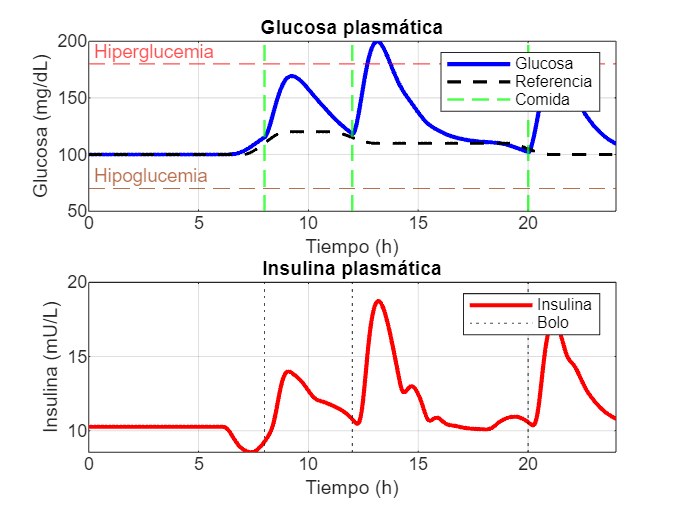


%% A3. BUCLE PRINCIPAL DE CÁLCULO LQR
for i = 1:num_points
    G_target_mgdl = operating_points_mgdl(i);
    G_target_mmolL = G_target_mgdl / 18.0156;

    %fprintf('Procesando punto de operación: %d mg/dL\n', G_target_mgdl);

    % Configuración inicial para fsolve
    z_guess = [p.VG * p.body_weight_kg * G_target_mmolL;
               p.VG * p.body_weight_kg * G_target_mmolL;
               1000; 1000; 5; 0.01; 0.01; 0.01; 0.015];

    options = optimset('Display', 'off', 'TolFun', 1e-12);
    [z_solution, ~, exitflag] = fsolve(@(z) steady_state_equations(z, p, G_target_mmolL), z_guess, options);

    if exitflag < 1
        continue;
    end

    % Extracción de solución
    x_eq = z_solution(1:8);
    u_eq = z_solution(9);

    % Linearización del modelo
    [A, B] = linearize_hovorka(p, x_eq, u_eq);

    % Matrices de ponderación adaptativas
    Q = diag([1, 0, 0, 0, 0.1, 0, 0, 0]);
    if G_target_mgdl >= 180
        R = 15;
    else
        R = 60;
    end

    % Cálculo de ganancias LQR
    try
        K = lqr(A, B, Q, R);
    catch
        continue;
    end

    % Almacenamiento de resultados
    op_points_actual(i) = G_target_mgdl;
    basal_rates(i) = u_eq;
    lqr_gains{i} = K;
    equilibrium_states{i} = x_eq';
end

% Creación de la tabla de resultados
gain_schedule_table_lqr = table(op_points_actual, basal_rates, lqr_gains, equilibrium_states, ...
    'VariableNames', {'Glucose_mgdl', 'Basal_U_min', 'K_lqr', 'x_eq'});
gain_schedule_table_lqr = gain_schedule_table_lqr(gain_schedule_table_lqr.Glucose_mgdl > 0, :);

%fprintf('\nPARTE A completada. Tabla de ganancias LQR (Adaptativa) generada en memoria.\n');
%% B1. PREPARACIÓN PARA LA SIMULACIÓN
%fprintf('\nIniciando PARTE B: Simulación LQR de 24 horas...\n');

% Extracción de datos de la tabla
G_points = gain_schedule_table_lqr.Glucose_mgdl;
Basal_points = gain_schedule_table_lqr.Basal_U_min;
K_matrices = cell2mat(gain_schedule_table_lqr.K_lqr);
X_eq_matrix = cell2mat(gain_schedule_table_lqr.x_eq);

% Configuración de simulación
dt = 1;
T = 24 * 60;
t = 0:dt:T;
N = numel(t);
meals.times = [8 * 60, 12 * 60, 20 * 60];
meals.grams = [30, 60, 50];

% Obtenemos el estado y basal iniciales DIRECTAMENTE de la tabla
idx_100 = find(G_points == 100);
if isempty(idx_100) % Si 100 no es un punto exacto
    idx_100 = find(abs(G_points - 100) == min(abs(G_points - 100)), 1);
end
x_inicial = X_eq_matrix(idx_100, :)'; % Se obtiene el estado de la tabla

%INICIALIZACIÓN DE VARIABLES DE REGISTRO
G = zeros(1, N);
REF = zeros(1, N);
u_total_log = zeros(1, N);
X_log = zeros(8, N); % Matriz para guardar el historial de estados
x = x_inicial;
X_log(:, 1) = x; % Guardar el estado inicial
G(1) = (x(1) / (p.VG * p.body_weight_kg)) * 18.0156;

%% B2. BUCLE DE SIMULACIÓN PRINCIPAL
for k = 1:N - 1
    % Cálculo de glucosa actual
    Gmg = (x(1) / (p.VG * p.body_weight_kg)) * 18.0156;
    REF(k) = ref_curve(t(k));

    % Cálculo de referencia futura para programación
    future_horizon = 65;
    t_future = t(k) + future_horizon;
    if t_future > T
        t_future = T;
    end
    REF_future = ref_curve(t_future);

    % Glucosa de programación ponderada
    weight = 0.35;
    scheduling_glucose = weight * Gmg + (1 - weight) * REF_future;

    % Interpolación de ganancias y puntos de equilibrio
    K_interp = zeros(1, 8);
    for j = 1:8
        K_interp(j) = interp1(G_points, K_matrices(:, j), scheduling_glucose, 'linear', 'extrap');
    end

    u_eq = interp1(G_points, Basal_points, scheduling_glucose, 'linear', 'extrap');

    x_eq_interp = zeros(8, 1);
    for j = 1:8
        x_eq_interp(j) = interp1(G_points, X_eq_matrix(:, j), scheduling_glucose, 'linear', 'extrap');
    end

    % Cálculo de acción de control
    u_lqr_U_min = -K_interp * (x - x_eq_interp);

    % Error respecto a la referencia
    error_ref = Gmg - REF(k);

    % Ganancia proporcional del seguimiento (ajustable)
    k_ref = 0.01;

    % Término correctivo proporcional
    correction_term = -k_ref * error_ref;

    % Acción total con saturación inferior en 0
    u_total_U_min = max(0, u_eq + u_lqr_U_min + correction_term);

    uTot_mU = u_total_U_min * 1000;

    % Integración del modelo
    dx = hovorka_plant(t(k), x, p, uTot_mU / 1000, meals);
    x = x + dx * dt;
    
    % ---- REGISTRO DE DATOS (AÑADIDO) ----
    X_log(:, k + 1) = x; % Registrar el nuevo estado
    
    % Registro de resultados
    G(k + 1) = (x(1) / (p.VG * p.body_weight_kg)) * 18.0156;
    u_total_log(k) = uTot_mU;
end

% Completar últimos valores
REF(N) = REF(N - 1);
u_total_log(N) = u_total_log(N - 1);

% --- Preparación de datos para graficar ---
t_h = t / 60; % Convertir tiempo a horas para los ejes X

% Extraer variables desde los datos registrados en la simulación
glucosa = G;
ref_glucosa = REF;
Q1 = X_log(1, :); % Corregido (antes era log(1,:))
Q2 = X_log(2, :);
insulina = X_log(5, :);
x1_accion = X_log(6, :);
x2_accion = X_log(7, :);
x3_accion = X_log(8, :);
u_aplicada = u_total_log / 1000; % Convertir de mU/min a U/min

% Calcular Tasa de Aparición de Insulina (UI) desde el estado S2
% UI = S2/t_maxI, donde S2 es el estado x(4)
UI = X_log(4, :) / p.t_maxI;

% Calcular Absorción de Glucosa Intestinal (UG) para graficar
UG_log = zeros(1, N);
for k = 1:N
    ug_k = 0;
    if ~isempty(meals.times)
        for i = 1:numel(meals.times)
            tau = t(k) - meals.times(i); % tau en minutos
            if tau >= 0
                Dg_mmol = (meals.grams(i) * 1000) / 180.156;
                ug_k = ug_k + (p.AG * Dg_mmol * tau * exp(-tau / p.t_maxG)) / (p.t_maxG^2);
            end
        end
    end
    UG_log(k) = ug_k;
end

% Tiempos de comida en horas
meal_times_h = meals.times / 60;

figure('Name', 'Resultados de Simulación Detallados', 'NumberTitle', 'off', 'Position', [50 50 1200 900]);

% --- Fila 1 ---

% SUBPLOT (1): Glucosa plasmática
subplot(2,1,1);
p_gluc = plot(t_h, glucosa, 'b', 'LineWidth', 2);
hold on;
p_ref = plot(t_h, ref_glucosa, 'k--', 'LineWidth', 1.5);
yline(180, 'r--', 'Hiperglucemia', 'LabelHorizontalAlignment', 'left', 'FontSize', 9);
yline(70, 'Color', [0.6 0.2 0], 'LineStyle', '--', 'Label', 'Hipoglucemia', 'LabelHorizontalAlignment', 'left', 'FontSize', 9);
p_comida = xline(meal_times_h, 'g--', 'LineWidth', 1.2);
hold off;
title('Glucosa plasmática');
xlabel('Tiempo (h)');
ylabel('Glucosa (mg/dL)');
legend([p_gluc, p_ref, p_comida(1)], {'Glucosa', 'Referencia', 'Comida'}, 'Location', 'NorthEast');
grid on;
xlim([0, 24]);

% SUBPLOT (2): Insulina plasmática
subplot(2,1,2);
p_ins = plot(t_h, insulina, 'r', 'LineWidth', 2);
hold on;
p_bolo = xline(meal_times_h, 'k:');
hold off;
title('Insulina plasmática');
xlabel('Tiempo (h)');
ylabel('Insulina (mU/L)');
legend([p_ins, p_bolo(1)], {'Insulina', 'Bolo'}, 'Location', 'NorthEast');
grid on;
xlim([0, 24]);


%% ========================================================================
%  PARTE C: CÁLCULO DE ÍNDICES DE DESEMPEÑO
% =========================================================================
fprintf('\nIniciando PARTE C: Cálculo de índices de desempeño...\n');


Iniciando PARTE C: Cálculo de índices de desempeño...



error_glucosa = G - REF;
t_min = t; % tiempo en minutos
dt = 1; % paso de tiempo en minutos

IAE = sum(abs(error_glucosa)) * dt;
ISE = sum(error_glucosa.^2) * dt;
ITAE = sum(t_min .* abs(error_glucosa)) * dt;

fprintf('IAE  = %.2f mg·min/dL\n', IAE);

IAE  = 28184.01 mg·min/dL


fprintf('ISE  = %.2f (mg/dL)^2·min\n', ISE);

ISE  = 1443848.66 (mg/dL)^2·min


fprintf('ITAE = %.2f mg·min²/dL\n', ITAE);

ITAE = 26326384.37 mg·min²/dL



%% --- FUNCIONES AUXILIARES ---
function F = steady_state_equations(z, p, G_target_mmolL)
    x = z(1:8);
    u = z(9);
    dx = hovorka_plant(0, x, p, u, struct('times', [], 'grams', []));
    G_actual_mmolL = x(1) / (p.VG * p.body_weight_kg);
    glucose_error = G_actual_mmolL - G_target_mmolL;
    F = [dx; glucose_error];
end

function [A, B] = linearize_hovorka(p, x_eq, u_eq)
    n_states = length(x_eq);
    n_inputs = length(u_eq);
    A = zeros(n_states, n_states);
    B = zeros(n_states, n_inputs);
    perturbation = 1e-6;

    f_eq = hovorka_plant(0, x_eq, p, u_eq, struct('times', [], 'grams', []));

    for j = 1:n_states
        x_perturbed = x_eq;
        x_perturbed(j) = x_perturbed(j) + perturbation;
        f_perturbed = hovorka_plant(0, x_perturbed, p, u_eq, struct('times', [], 'grams', []));
        A(:, j) = (f_perturbed - f_eq) / perturbation;
    end

    for j = 1:n_inputs
        u_perturbed = u_eq;
        u_perturbed(j) = u_perturbed(j) + perturbation;
        f_perturbed = hovorka_plant(0, x_eq, p, u_perturbed, struct('times', [], 'grams', []));
        B(:, j) = (f_perturbed - f_eq) / perturbation;
    end
end

function dx = hovorka_plant(t, x, p, u, meals)
    Q1 = x(1); Q2 = x(2); S1 = x(3); S2 = x(4); I = x(5);
    x1 = x(6); x2 = x(7); x3 = x(8);

    V_G_total = p.VG * p.body_weight_kg;

    if V_G_total > 0
        G_mmol_L = Q1 / V_G_total;
    else
        G_mmol_L = 0;
    end

    if G_mmol_L > 0
        if G_mmol_L < 4.5
            F01c_term = p.F01 / (4.5 * p.VG);
        else
            F01c_term = p.F01 / (G_mmol_L * p.VG);
        end
    else
        F01c_term = p.F01 / (4.5 * p.VG);
    end

    if G_mmol_L >= 9
        Fr = 0.003 * (G_mmol_L - 9) * V_G_total;
    else
        Fr = 0;
    end

    UG = 0;
    if ~isempty(meals.times)
        for i = 1:numel(meals.times)
            tau = t - meals.times(i);
            if tau >= 0
                Dg_mmol = (meals.grams(i) * 1000) / 180.156;
                UG = UG + (p.AG * Dg_mmol * tau * exp(-tau / p.t_maxG)) / (p.t_maxG^2);
            end
        end
    end

    EGP = p.EGP0 * p.body_weight_kg;

    dQ1 = -(F01c_term + x1) * Q1 + (p.k12 * Q2) - Fr + UG + EGP * (1 - x3);
    dQ2 = x1 * Q1 - (p.k12 + x2) * Q2;

    u_pmol = u * 6000;
    dS1 = u_pmol - (S1 / p.t_maxI);
    dS2 = (S1 / p.t_maxI) - (S2 / p.t_maxI);

    UI_pmol = S2 / p.t_maxI;
    I_pmol_L = I * 6.945;
    dI_pmol_L = (UI_pmol / (p.VI * p.body_weight_kg)) - p.ke * I_pmol_L;
    dI = dI_pmol_L / 6.945;

    dx1 = -p.ka1 * x1 + p.kb1 * I;
    dx2 = -p.ka2 * x2 + p.kb2 * I;
    dx3 = -p.ka3 * x3 + p.kb3 * I;

    dx = [dQ1; dQ2; dS1; dS2; dI; dx1; dx2; dx3];
end

function r = ref_curve(t_min)
    h = mod(t_min / 60, 24);

    if h < 7
        r = 100;
    elseif h < 9
        a = (h - 7) / 2;
        r = 100 + (120 - 100) * (3 * a^2 - 2 * a^3);
    elseif h < 11
        r = 120;
    elseif h < 13
        a = (h - 11) / 2;
        r = 120 + (110 - 120) * (3 * a^2 - 2 * a^3);
    elseif h < 19
        r = 110;
    elseif h < 21
        a = (h - 19) / 2;
        r = 110 + (100 - 110) * (3 * a^2 - 2 * a^3);
    else
        r = 100;
    end
end